# Example: MHKiT-MATLAB WEC-Sim

This example loads simulated data from a WEC-Sim run for a two-body point absorber (Reference Model 3) and demonstrates the application of the MHKiT wave module to interact with the simulated data. The analysis is broken down into three parts:

1. Load WEC-Sim Simulated Data

2. WEC-Sim Simulated Data

- Wave Class Data

- Body Class Data

- PTO Class Data

- Constraint Class Data

- Mooring Class Data

3. Apply MHKiT Wave Module

## 1. Load WEC-Sim Simulated Data

WEC-Sim saves output data as a MATLAB structure, generated by WEC-Sim's Response Class. The WEC-Sim structure contains data for Wave, Bodies, PTOs, Constraints, Mooring, MoorDyn, and PTOSim classes.

% Relative location and filename of simulated WEC-Sim data (run with mooring)
filename = './examples/data/RM3MooringMatrix_matlabWorkspace.mat'

filename = './examples/data/RM3MooringMatrix_matlabWorkspace.mat'

load(filename, 'output');

## 2. WEC-Sim Simulated Data

Wave Class Data Data from WEC-Sim's Wave Class includes information about the wave input, including the wave type and wave elevation as a function of time.

Store WEC-Sim output from the Wave Class

wave_data = output.wave;

Display the wave type from the WEC-Sim Wave Class

fprintf('WEC-Sim wave type: %s\n', wave_data.type);

WEC-Sim wave type: etaImport


Plot Wave Elevation Data

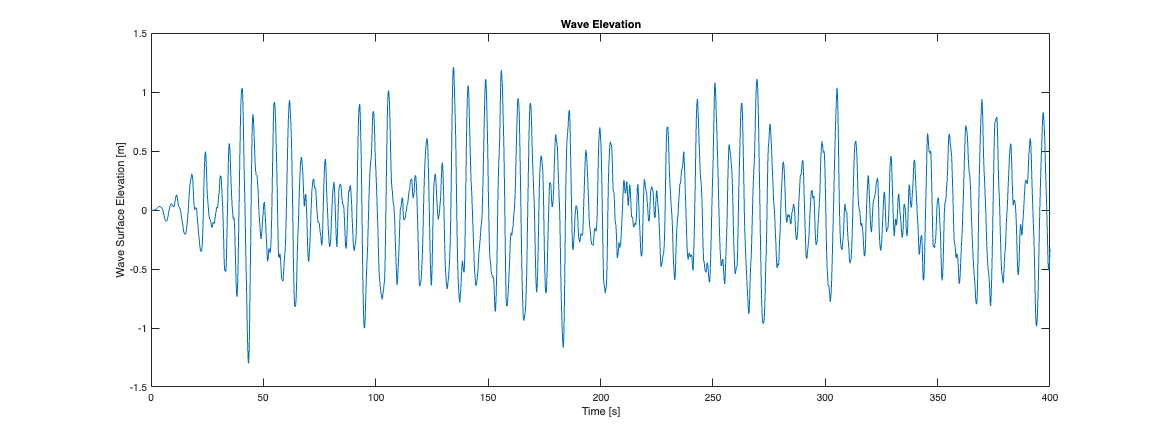

figure('Position', [100, 100, 1600, 600]);
plot(wave_data.time, wave_data.elevation);
xlabel('Time [s]');
ylabel('Wave Surface Elevation [m]');
title('Wave Elevation');

## Body Class Data

Data from WEC-Sim's Body Class includes information about each body, including position, velocity, acceleration, forces, and body name.

Store WEC-Sim output from the Body Class

bodies = output.bodies;

Body Class Data for Body 1

body1 = bodies(1);
fprintf('Name of Body 1: %s\n', body1.name);

Name of Body 1: float


Plot heave position data for Body 1

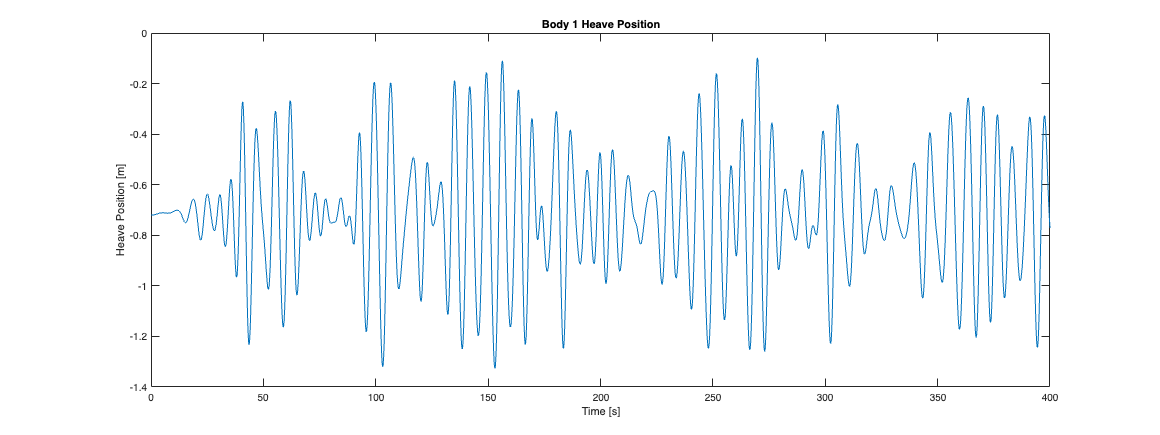

figure('Position', [100, 100, 1600, 600]);
plot(body1.time, body1.position(:,3));
xlabel('Time [s]');
ylabel('Heave Position [m]');
title('Body 1 Heave Position');

Calculate and display max/min heave position

fprintf('Body 1 max heave position = %.4f [m]\n', max(body1.position(:,3)));

Body 1 max heave position = -0.0975 [m]


fprintf('Body 1 min heave position = %.4f [m]\n', min(body1.position(:,3)));

Body 1 min heave position = -1.3264 [m]


Plot Body 1 position data for all DOFs

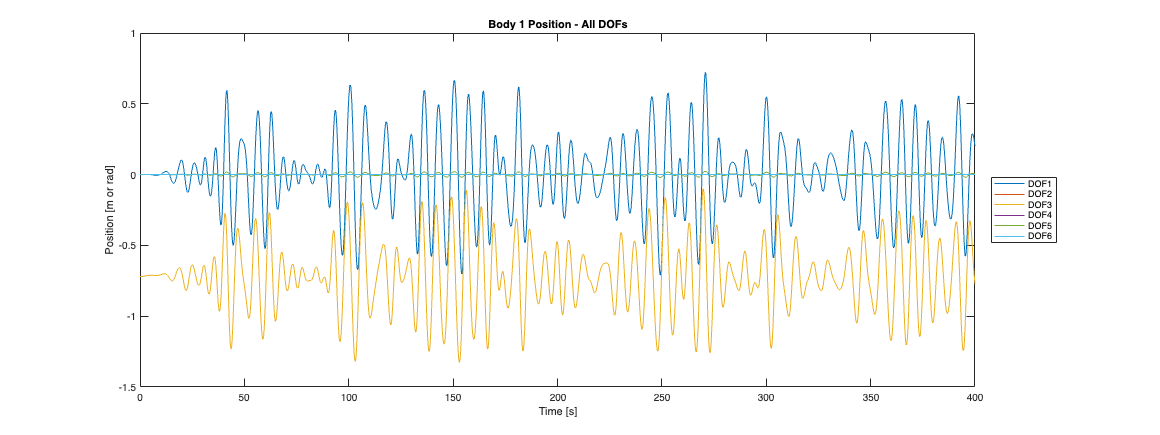

figure('Position', [100, 100, 1600, 600]);
plot(body1.time, body1.position);
xlabel('Time [s]');
ylabel('Position [m or rad]');
title('Body 1 Position - All DOFs');
legend('DOF1', 'DOF2', 'DOF3', 'DOF4', 'DOF5', 'DOF6', 'Location', 'eastoutside');

Body Class Data for Body 2

body2 = bodies(2);
fprintf('Name of Body 2: %s\n', body2.name);

Name of Body 2: spar


body2

body2 = struct with fields:
                       name: 'spar'
                       time: [40001×1 double]
                   position: [40001×6 double]
                   velocity: [40001×6 double]
               acceleration: [40001×6 double]
                 forceTotal: [40001×6 double]
            forceExcitation: [40001×6 double]
      forceRadiationDamping: [40001×6 double]
             forceAddedMass: [40001×6 double]
             forceRestoring: [40001×6 double]
    forceMorrisonAndViscous: [40001×6 double]
         forceLinearDamping: [40001×6 double]


## PTO Class Data

Data from WEC-Sim's PTO Class includes information about each PTO, including position, velocity, acceleration, forces, and PTO name.

Store WEC-Sim output from the PTO Class

ptos = output.ptos;
fprintf('Name of PTO: %s\n', ptos.name);

Name of PTO: PTO1


Plot PTO power

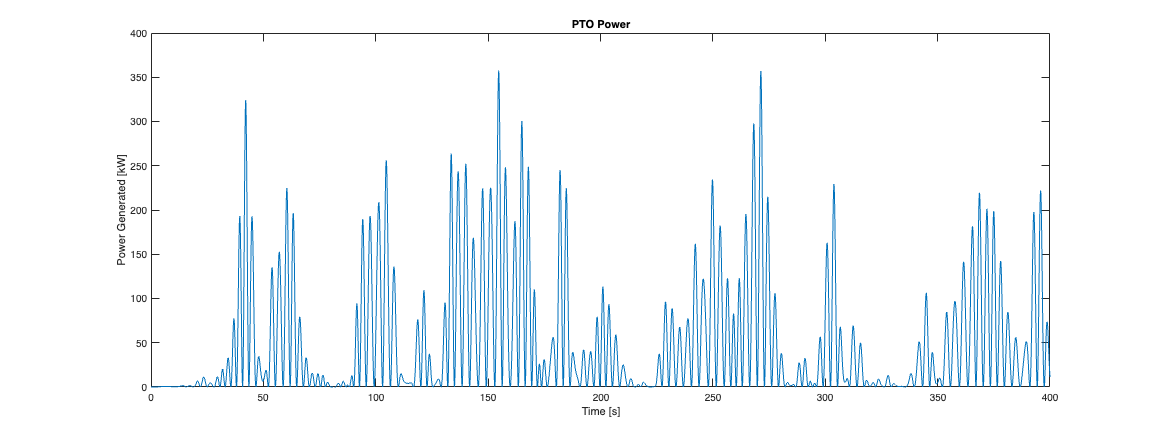

figure('Position', [100, 100, 1600, 600]);
plot(ptos.time, -1 * ptos.powerInternalMechanics(:,3) / 1000);
xlabel('Time [s]');
ylabel('Power Generated [kW]');
title('PTO Power');

## Constraint Class Data

Data from WEC-Sim's Constraint Class includes information about each constraint, including position, velocity, acceleration, forces, and constraint name.

constraints = output.constraints;
fprintf('Name of Constraint: %s\n', constraints.name);

Name of Constraint: Constraint1


constraints

constraints = struct with fields:
               name: 'Constraint1'
               time: [40001×1 double]
           position: [40001×6 double]
           velocity: [40001×6 double]
       acceleration: [40001×6 double]
    forceConstraint: [40001×6 double]


## Mooring Class Data

Data from WEC-Sim's Mooring Class includes information about the mooring, including position, velocity, mooring force, and mooring name.

mooring = output.mooring;
mooring

mooring = struct with fields:
            name: 'mooring'
            time: [40001×1 double]
        position: [40001×6 double]
        velocity: [40001×6 double]
    forceMooring: [40001×6 double]


## 3. Apply MHKiT Wave Module

Calculate spectrum from the WEC-Sim wave elevation timeseries data using the MHKiT elevation_spectrum function.

Calculate wave spectrum

sample_rate = 60;
nnft = 1000;  % Number of bins in the Fast Fourier Transform
ws_spectrum = elevation_spectrum(wave_data.elevation, sample_rate, nnft, wave_data.time);

Plot calculated wave spectrum

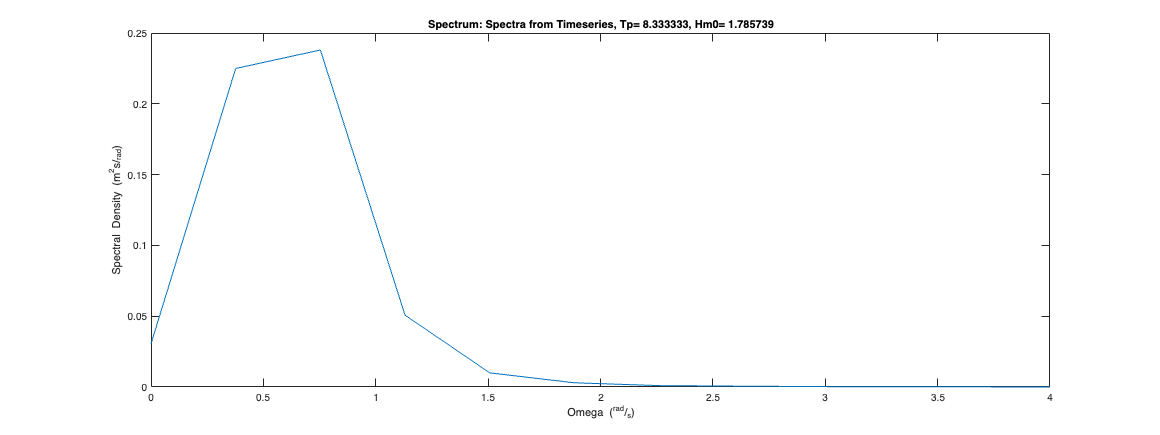

figure('Position', [100, 100, 1600, 600]);
plot_spectrum(ws_spectrum);
xlim([0, 4]);

Calculate Peak Wave Period (Tp) and Significant Wave Height (Hm0)

Tp = peak_period(ws_spectrum);
Hm0 = significant_wave_height(ws_spectrum);

fprintf('Peak Wave Period (Tp) = %.4f s\n', Tp);

Peak Wave Period (Tp) = 8.3333 s


fprintf('Significant Wave Height (Hm0) = %.4f m\n', Hm0);

Significant Wave Height (Hm0) = 1.7857 m
